# Time Domain Optimization - Free Decay

## Define all shared variables

clc; clear;

% Run Read_AQWA and process_hydro
hydro = struct();
hydro = Read_AQWA2(hydro,'BEMData/FullScale/ANALYSIS.ah1','BEMData/FullScale/ANALYSIS.lis');

% Wave Data 
T_wave = 6;
h_wave = 0.5;
BEM = process_hydro(hydro,T_wave);

% Body
load("bodies/body.mat")

% Mass ratio
mu = 0.05;

m1 = body.m1;
m = (m1*mu)/3;

body.m = m;

% Tuned Parameters
k = 15000;
c = 1000;
k_i = 1000;
b = 15000;

tmd_TMD = [k c];
tmd_TID = [k c k_i b];

% Length of simulation
t = 0:0.05:250;

## Set up optimization

k_lb = 1000; k_ub = 50000;
c_lb = 10; c_ub = 20000;
k_i_lb = 10; k_i_ub = 5000;
b_lb = 100; b_ub = 20000;

lb_TMD = [k_lb,c_lb];
ub_TMD = [k_ub,c_ub];

lb_TID = [k_lb,c_lb,k_i_lb,b_lb];
ub_TID = [k_ub,c_ub,k_i_ub,b_ub];

## Set up initial conditions - heave

r0_baseline = [0 3 deg2rad(0)];
v0_baseline = [0 0 0];
y0_baseline = [r0_baseline v0_baseline];

r0_TMD = [0 3 deg2rad(0) body.L2_0 body.L3_0 body.L4_0];
v0_TMD = [0 0 0 0 0 0];
y0_TMD = [r0_TMD v0_TMD];

r0_TID = [0 3 deg2rad(0) body.L2_0 body.L3_0 body.L4_0 body.L5_0 body.L6_0 body.L7_0];
v0_TID = [0 0 0 0 0 0 0 0 0];
y0_TID = [r0_TID v0_TID];

## Run optimization - heave



Iter     Func-count       f(x)      MeshSize     Method
    0           1       0.968676             1      
    1           2       0.900151             2     Successful Poll
    2           4       0.869174             4     Successful Poll
    3           5       0.823282             8     Successful Poll
    4           6       0.769085            16     Successful Poll
    5           7         0.7336            32     Successful Poll
    6           7         0.7336            16     Refine Mesh
    7           7         0.7336             8     Refine Mesh
    8           8         0.7336             4     Refine Mesh
    9           9       0.732441             8     Successful Poll
   10          10       0.732441             4     Refine Mesh
   11          10       0.732441             2     Refine Mesh
   12          14       0.732441             1     Refine Mesh
   13          15       0.681792             2     Successful Poll
   14          19       0.679382          

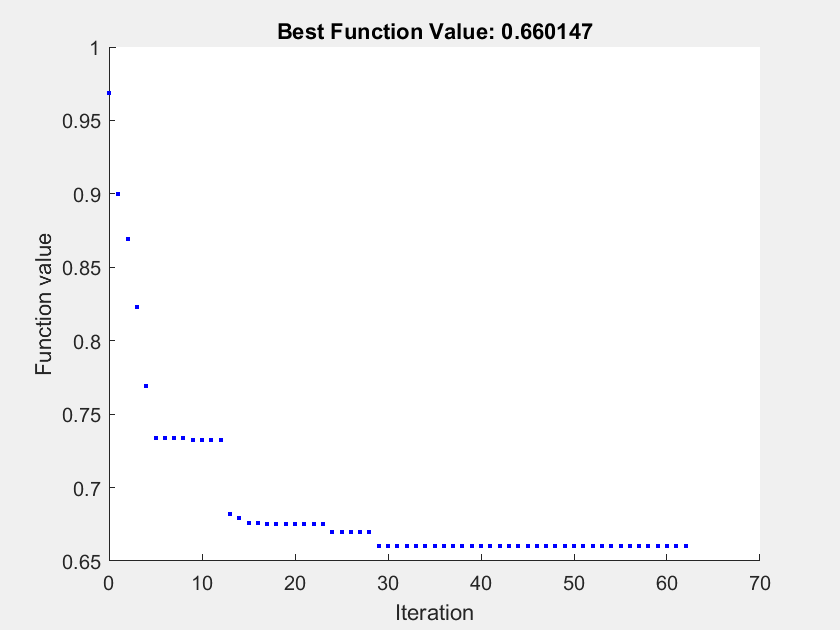

options = optimoptions('patternsearch','Display','iter','PlotFcn',@psplotbestf,'MeshTolerance',1e-3,'MaxIterations',2400,'Cache','on');

f_TMD = @(tmd) objfun_TD_FreeDecay(t,body,BEM,y0_TMD,tmd,'TMD','heave');
[tmd_opt, fval_TMD] = patternsearch(f_TMD,tmd_TMD,[],[],[],[],lb_TMD,ub_TMD,[],options);


% f_TID = @(tmd) objfun_TD_FreeDecay(t,body,BEM,y0_TID,tmd,'TID','heave');
% [tid_opt, fval_TID] = patternsearch(f_TID,tmd_TID,[],[],[],[],lb_TID,ub_TID,[],options);

## Run studies - heave

[t, x_baseline_noWave] = run_dynamic_study(t,body,BEM,y0_baseline,'PTO','No PTO','waveType','No Wave');
[t, x_TMD_noWave] = run_dynamic_study(t,body,BEM,y0_TMD,tmd_opt,'PTO','TMD','waveType','No Wave');
% [t, x_TID_noWave] = run_dynamic_study(t,body,BEM,y0_TID,round(tid_opt),'PTO','TID','waveType','No Wave');

## Plot results - heave

figure(1)
plot(t,x_baseline_noWave(:,2),'k','LineWidth',2)
hold on
plot(t,x_TMD_noWave(:,2),'b','LineWidth',2)
% plot(t,x_TID_noWave(:,2),'r','LineWidth',2)
xlim([0 250])
set(gca,'FontSize',12)
xlabel('Time (s)')
ylabel('Heave (m)')
legend('No Control','TMD','TID')

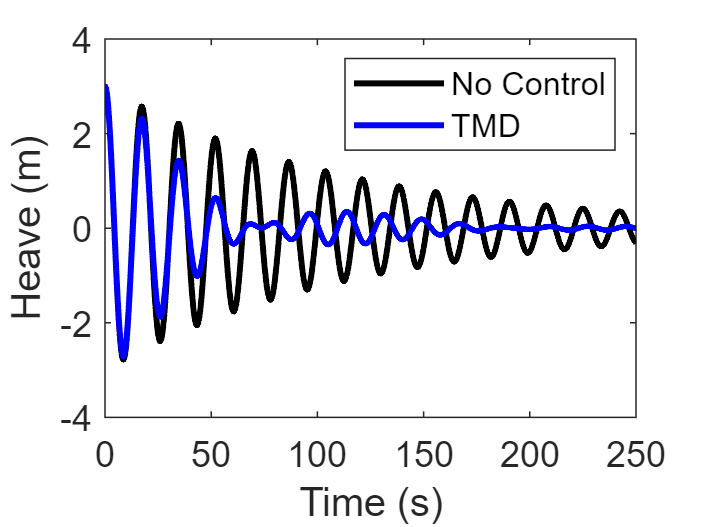

hold off

## Set up initial conditions - pitch

r0_baseline = [0 0 deg2rad(5)];
v0_baseline = [0 0 0];
y0_baseline = [r0_baseline v0_baseline];

r0_TMD = [0 0 deg2rad(5) body.L2_0 body.L3_0 body.L4_0];
v0_TMD = [0 0 0 0 0 0];
y0_TMD = [r0_TMD v0_TMD];

r0_TID = [0 0 deg2rad(5) body.L2_0 body.L3_0 body.L4_0 body.L5_0 body.L6_0 body.L7_0];
v0_TID = [0 0 0 0 0 0 0 0 0];
y0_TID = [r0_TID v0_TID];


## Run optimization - pitch



Iter     Func-count       f(x)      MeshSize     Method
    0           1        1.68906             1      
    1           2        1.68906             2     Successful Poll
    2           3        1.68906             4     Successful Poll
    3           4        1.68905             8     Successful Poll
    4           5        1.68904            16     Successful Poll
    5           6        1.68903            32     Successful Poll
    6           7        1.68901            64     Successful Poll
    7           8        1.68895           128     Successful Poll
    8           9        1.68882           256     Successful Poll
    9          10        1.68855           512     Successful Poll
   10          11        1.68785          1024     Successful Poll
   11          12        1.68571          2048     Successful Poll
   12          13         1.6693          4096     Successful Poll
   13          14         1.6693          2048     Refine Mesh
   14          16     

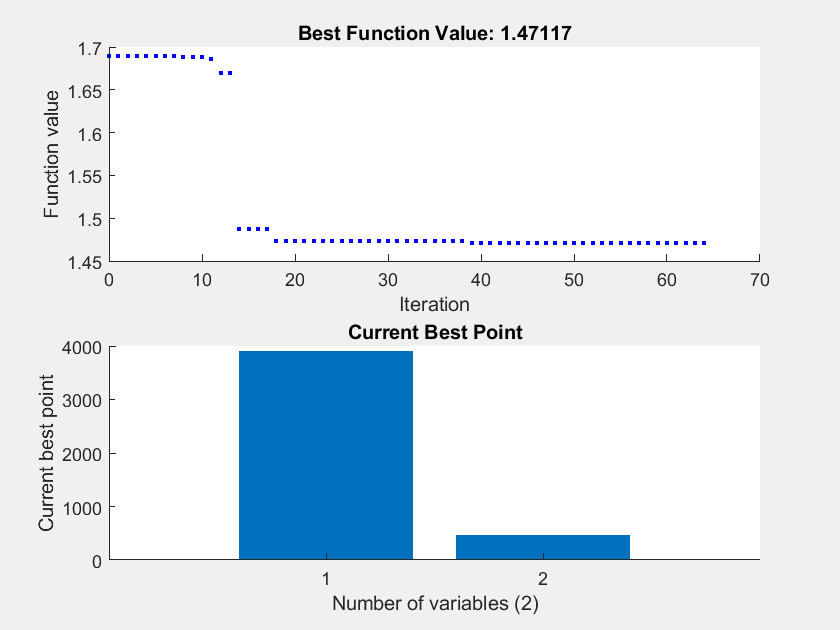

options = optimoptions('patternsearch','Display','iter','PlotFcn',["psplotbestf","psplotbestx"],'MeshTolerance',1e-3,'MaxIterations',2400,'Cache','off');

f_TMD = @(tmd) objfun_TD_FreeDecay(t,body,BEM,y0_TMD,tmd,'TMD','pitch');
[tmd_opt, fval_TMD] = patternsearch(f_TMD,tmd_TMD,[],[],[],[],lb_TMD,ub_TMD,[],options);



Iter     Func-count       f(x)      MeshSize     Method
    0           1        1.68818             1      
    1           2        1.68818             2     Successful Poll
    2           3        1.68818             4     Successful Poll
    3           4        1.68818             8     Successful Poll
    4           5        1.68817            16     Successful Poll
    5           6        1.68815            32     Successful Poll
    6           7        1.68811            64     Successful Poll
    7           8        1.68803           128     Successful Poll
    8           9        1.68787           256     Successful Poll
    9          10        1.68751           512     Successful Poll
   10          11        1.68659          1024     Successful Poll
   11          12        1.68365          2048     Successful Poll
   12          13        1.66064          4096     Successful Poll
   13          14        1.66064          2048     Refine Mesh
   14          16     

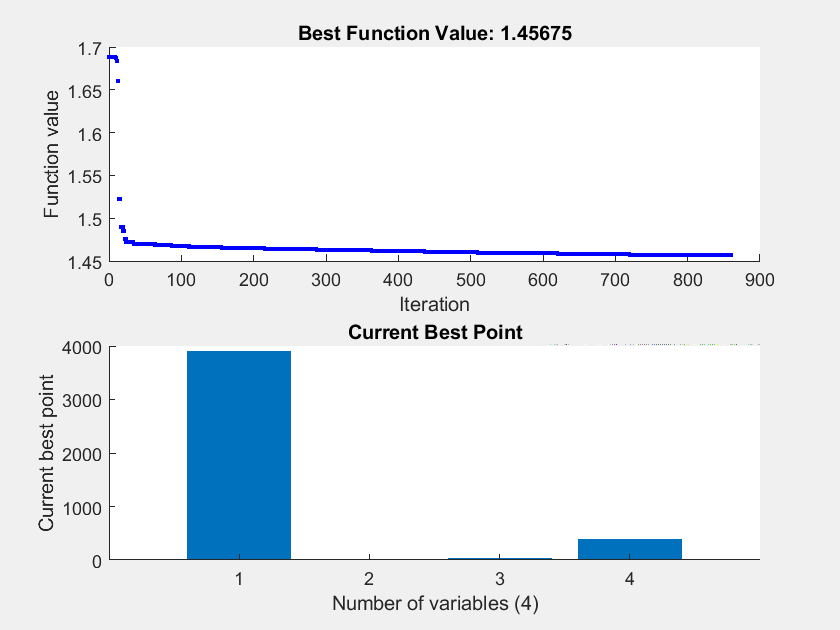


f_TID = @(tmd) objfun_TD_FreeDecay(t,body,BEM,y0_TID,tmd,'TID','pitch');
[tid_opt, fval_TID] = patternsearch(f_TID,tmd_TID,[],[],[],[],lb_TID,ub_TID,[],options);

## Run studies

[t, x_baseline_noWave] = run_dynamic_study(t,body,BEM,y0_baseline,'PTO','No PTO','waveType','No Wave');
[t, x_TMD_noWave] = run_dynamic_study(t,body,BEM,y0_TMD,tmd_opt,'PTO','TMD','waveType','No Wave');
[t, x_TID_noWave] = run_dynamic_study(t,body,BEM,y0_TID,tid_opt,'PTO','TID','waveType','No Wave');

## Plot results - pitch

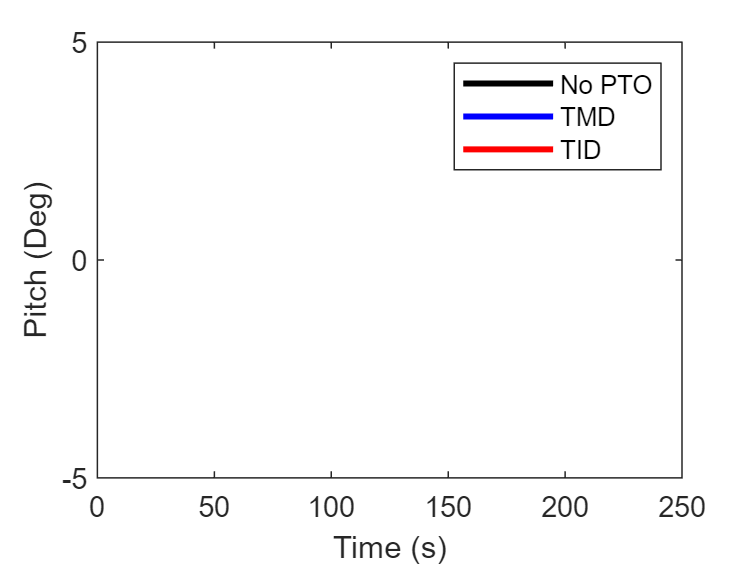

figure(2)
plot(t,x_baseline_noWave(:,3)*(180/pi),'k','LineWidth',2)
hold on
plot(t,x_TMD_noWave(:,3)*(180/pi),'b','LineWidth',2)
plot(t,x_TID_noWave(:,3)*(180/pi),'r','LineWidth',2)
xlabel('Time (s)')
ylabel('Pitch (Deg)')
legend('No PTO','TMD','TID')
hold off